% ============================================================
% TEST_CONSISTENT_TANGENT
%
% Verifies the consistent constitutive tangent for:
%
%   1. none
%   2. amor
%   3. spectral
%
% using a directional finite-difference test:
%
%       Ctan * dEps
%
% versus
%
%       [sigma(Eps+h*dEps)-sigma(Eps)]/h
%
% ============================================================

clear;
clc;

%% ============================================================
% MATERIAL
% =============================================================

material.E  = 210000;
material.nu = 0.30;
material.xk = 1e-8;

model.dim     = 2;
model.splitEta = 1e-12;


%% ============================================================
% FINITE DIFFERENCE PARAMETERS
% =============================================================

h = 1e-7;

nTests = 8;


%% ============================================================
% DEFINE STRAIN STATES
%
% Engineering strain:
%
% [exx; eyy; gamma_xy]
% =============================================================

eps0 = 1e-3;

strainStates = zeros(3,nTests);

strainNames = cell(nTests,1);

% ------------------------------------------------------------
% 1. Pure tension
% ------------------------------------------------------------

strainStates(:,1) = [
    eps0;
    0;
    0
];

strainNames{1} = 'Pure tension';


% ------------------------------------------------------------
% 2. Pure compression
% ------------------------------------------------------------

strainStates(:,2) = [
    -eps0;
    0;
    0
];

strainNames{2} = 'Pure compression';


% ------------------------------------------------------------
% 3. Equibiaxial tension
% ------------------------------------------------------------

strainStates(:,3) = [
    eps0;
    eps0;
    0
];

strainNames{3} = 'Equibiaxial tension';


% ------------------------------------------------------------
% 4. Equibiaxial compression
% ------------------------------------------------------------

strainStates(:,4) = [
    -eps0;
    -eps0;
    0
];

strainNames{4} = 'Equibiaxial compression';


% ------------------------------------------------------------
% 5. Pure shear
% ------------------------------------------------------------

strainStates(:,5) = [
    0;
    0;
    eps0
];

strainNames{5} = 'Pure shear';


% ------------------------------------------------------------
% 6. Mixed tension/compression
% ------------------------------------------------------------

strainStates(:,6) = [
    eps0;
    -0.5*eps0;
    0
];

strainNames{6} = 'Mixed tension/compression';


% ------------------------------------------------------------
% 7. Mixed shear
% ------------------------------------------------------------

strainStates(:,7) = [
    eps0;
    -0.3*eps0;
    0.8*eps0
];

strainNames{7} = 'Mixed shear';


% ------------------------------------------------------------
% 8. General strain state
% ------------------------------------------------------------

strainStates(:,8) = [
    0.7*eps0;
    -0.4*eps0;
    0.6*eps0
];

strainNames{8} = 'General strain';


%% ============================================================
% SPLITS
% =============================================================

splitNames = {
    'none'
    'amor'
    'spectral'
};

nSplits = numel(splitNames);


%% ============================================================
% RANDOM PERTURBATION DIRECTION
%
% Use a different perturbation for every test.
% =============================================================

rng(10);

dEpsAll = randn(3,nTests);

for i = 1:nTests

    dEpsAll(:,i) = ...
        dEpsAll(:,i) / ...
        norm(dEpsAll(:,i));

end


%% ============================================================
% STORAGE
% =============================================================

relativeError = zeros(nTests,nSplits);
absoluteError = zeros(nTests,nSplits);

analyticalNorm = zeros(nTests,nSplits);
numericalNorm   = zeros(nTests,nSplits);


%% ============================================================
% RUN TESTS
% =============================================================

for s = 1:nSplits

    model.split = splitNames{s};

    fprintf('\n');
    fprintf('============================================================\n');
    fprintf(' SPLIT: %s\n',upper(model.split));
    fprintf('============================================================\n');

    for i = 1:nTests

        %% ----------------------------------------------------
        % Current strain
        % -----------------------------------------------------

        eps = strainStates(:,i);

        %% ----------------------------------------------------
        % Perturbation direction
        % -----------------------------------------------------

        dEps = dEpsAll(:,i);

        %% ----------------------------------------------------
        % Analytical tangent
        % -----------------------------------------------------

        split = computeSplitInfo( ...
            eps, ...
            material, ...
            model);

        Ctan = split.Csplit;

        analytical = Ctan*dEps;

        %% ----------------------------------------------------
        % Numerical derivative
        % -----------------------------------------------------

        splitPerturbed = computeSplitInfo( ...
            eps + h*dEps, ...
            material, ...
            model);

        sigma0 = ...
            stressTensorToVoigt( ...
            split.sigmaPlus + ...
            split.sigmaMinus, ...
            model.dim);

        sigma1 = ...
            stressTensorToVoigt( ...
            splitPerturbed.sigmaPlus + ...
            splitPerturbed.sigmaMinus, ...
            model.dim);

        numerical = ...
            (sigma1-sigma0)/h;

        %% ----------------------------------------------------
        % Error
        % -----------------------------------------------------

        errorVec = analytical - numerical;

        absErr = norm(errorVec);

        relErr = ...
            absErr / ...
            max(norm(numerical),1e-16);

        absoluteError(i,s) = absErr;
        relativeError(i,s) = relErr;

        analyticalNorm(i,s) = norm(analytical);
        numericalNorm(i,s)   = norm(numerical);

        %% ----------------------------------------------------
        % Print
        % -----------------------------------------------------

        fprintf( ...
            '%-30s : abs = %.4e   rel = %.4e\n', ...
            strainNames{i}, ...
            absErr, ...
            relErr);

    end

end

 SPLIT: NONE


Pure tension                   : abs = 8.2945e-07   rel = 4.0484e-12
Pure compression               : abs = 2.2194e-07   rel = 7.4124e-13
Equibiaxial tension            : abs = 3.7440e-07   rel = 2.1071e-12
Equibiaxial compression        : abs = 5.6689e-07   rel = 5.5258e-12
Pure shear                     : abs = 3.7267e-08   rel = 1.3905e-13
Mixed tension/compression      : abs = 3.2245e-07   rel = 1.2123e-12
Mixed shear                    : abs = 7.1551e-08   rel = 1.9990e-13
General strain                 : abs = 2.6005e-07   rel = 7.3505e-13


 SPLIT: AMOR


Pure tension                   : abs = 8.2946e-07   rel = 4.0484e-12
Pure compression               : abs = 2.4429e-07   rel = 8.1590e-13
Equibiaxial tension            : abs = 7.1189e-07   rel = 4.0065e-12
Equibiaxial compression        : abs = 5.6690e-07   rel = 5.5259e-12
Pure shear                     : abs = 3.7267e-08   rel = 1.3905e-13
Mixed tension/compression      : abs = 1.8972e-07   rel = 7.1332e-13
Mixed shear                    : abs = 1.4057e-07   rel = 3.9274e-13
General strain                 : abs = 1.2724e-07   rel = 3.5966e-13


 SPLIT: SPECTRAL


Pure tension                   : abs = 8.2946e-07   rel = 4.0484e-12
Pure compression               : abs = 7.9501e-07   rel = 2.6552e-12
Equibiaxial tension            : abs = 7.1367e-07   rel = 4.0165e-12
Equibiaxial compression        : abs = 2.8225e-07   rel = 2.7513e-12
Pure shear                     : abs = 4.6782e-07   rel = 1.7455e-12
Mixed tension/compression      : abs = 2.6589e-07   rel = 9.9968e-13
Mixed shear                    : abs = 5.8659e-07   rel = 1.6388e-12
General strain                 : abs = 3.2928e-07   rel = 9.3072e-13




%% ============================================================
% SUMMARY
% =============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf(' TANGENT CONSISTENCY SUMMARY\n');

 TANGENT CONSISTENCY SUMMARY


fprintf('============================================================\n');


fprintf( ...
    '%-12s %18s %18s\n', ...
    'Split', ...
    'Max absolute error', ...
    'Max relative error');

Split        Max absolute error Max relative error



fprintf( ...
    '------------------------------------------------------------\n');

------------------------------------------------------------



for s = 1:nSplits

    fprintf( ...
        '%-12s %18.6e %18.6e\n', ...
        splitNames{s}, ...
        max(absoluteError(:,s)), ...
        max(relativeError(:,s)));

end

none               8.294547e-07       5.525796e-12
amor               8.294635e-07       5.525929e-12
spectral           8.294635e-07       4.048419e-12




%% ============================================================
% ERROR TABLE
% =============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf(' RELATIVE ERROR BY TEST\n');

 RELATIVE ERROR BY TEST


fprintf('============================================================\n');


fprintf('%-30s', 'Test');

Test                          


for s = 1:nSplits
    fprintf('%18s', splitNames{s});
end

              none              amor          spectral


fprintf('\n');

fprintf( ...
    '------------------------------------------------------------\n');

------------------------------------------------------------



for i = 1:nTests

    fprintf('%-30s',strainNames{i});

    for s = 1:nSplits

        fprintf( ...
            '%18.6e', ...
            relativeError(i,s));

    end

    fprintf('\n');

end

Pure tension                  

      4.048376e-12      4.048419e-12      4.048419e-12

Pure compression              

      7.412429e-13      8.158965e-13      2.655241e-12

Equibiaxial tension           

      2.107113e-12      4.006476e-12      4.016482e-12

Equibiaxial compression       

      5.525796e-12      5.525929e-12      2.751314e-12

Pure shear                    

      1.390487e-13      1.390487e-13      1.745495e-12

Mixed tension/compression     

      1.212346e-12      7.133178e-13      9.996840e-13

Mixed shear                   

      1.999010e-13      3.927369e-13      1.638826e-12

General strain                

      7.350468e-13      3.596555e-13      9.307209e-13

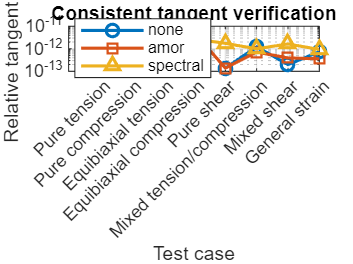



%% ============================================================
% PLOT
% =============================================================

figure('Color','w');

semilogy( ...
    1:nTests, ...
    relativeError(:,1), ...
    '-o', ...
    'LineWidth',1.5);

hold on;

semilogy( ...
    1:nTests, ...
    relativeError(:,2), ...
    '-s', ...
    'LineWidth',1.5);

semilogy( ...
    1:nTests, ...
    relativeError(:,3), ...
    '-^', ...
    'LineWidth',1.5);

grid on;

xlabel('Test case');
ylabel('Relative tangent error');

title('Consistent tangent verification');

set(gca, ...
    'XTick',1:nTests, ...
    'XTickLabel',strainNames, ...
    'XTickLabelRotation',45);

legend( ...
    splitNames, ...
    'Location','best');



%% ============================================================
% AUTOMATIC PASS/FAIL
% =============================================================

tolerance = 1e-5;

fprintf('\n');
fprintf('============================================================\n');

fprintf(' PASS / FAIL\n');

 PASS / FAIL


fprintf('============================================================\n');


for s = 1:nSplits

    maxErr = max(relativeError(:,s));

    if maxErr < tolerance

        fprintf( ...
            '%-12s : PASS   max error = %.4e\n', ...
            splitNames{s}, ...
            maxErr);

    else

        fprintf( ...
            '%-12s : FAIL   max error = %.4e\n', ...
            splitNames{s}, ...
            maxErr);

    end

end

none         : PASS   max error = 5.5258e-12
amor         : PASS   max error = 5.5259e-12
spectral     : PASS   max error = 4.0484e-12
